# Trial 2: Asymptotic Efficiency under Numerous Anchors

clear;
close all;
clc;

## 1. Settings

### 1.1 enviroment settings 

T=1; % no repeated ranging
N=2; % N tags
Room_Length=50; Room_Width=50; Robot_Size=5;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t=[0;25];

### 1.2 simulation settings

Q=[3,10,100,1000,10000];%anchor numbers
sigma = 0.1; %noise variance
L=10; %Monte-Carlo runs

%matrix to store simulation results
%ULS
Y0_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-ULS
Ye_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%MultiGN-ULS
Ym_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-SDP
Y1_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GTRS
Y2_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%Lower Bound
CRLB=zeros(length(T),2);

## 2. For different number M of anhors

for q = 1:length(Q)
    [A,S,M]=setting(T,Room_Length,Room_Width,Robot_Size,Q(q),N);
    %mse
    mse_R0_c=0; mse_R0_a=0; mse_t0=0;
    mse_Re_c=0; mse_Re_a=0; mse_te=0;
    mse_Rm_c=0; mse_Rm_a=0; mse_tm=0;
    mse_R1_c=0; mse_R1_a=0; mse_t1=0;
    mse_R2_c=0; mse_R2_a=0; mse_t2=0;

    %true distance
    Sa=R*S+t; %tags' global coordinate
    relative_position=zeros(2,M*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*M+1:i*M)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)';%(M*N,1)

#### CRLB

    Sigma=repmat(sigma,1,M*N);
    F=zeros(6,6); 
    W=1./(Sigma.^2);
    for i=1:N     
        s_bar=[S(:,i);1];
        for m=1:M
            score=kron(s_bar,eye(2))*relative_position(:,(i-1)*M+m)/sigma/relative_distance((i-1)*M+m);
            F=F+score*score';
        end
    end

#### ULS- precalculation    

    A_bar=A-(A*ones(M,1))*ones(1,M)/M;
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    H1=-2*kron(S',A_bar')*Psi;    %(N*M,2)
    H2=repmat(-2*A_bar',N,1); %(N*M,2)
    H=[H1,H2];       %(N*M,4)
    HtH_invHt=(H'*H)\H';

#### SDP- precalculation 

    c_norm = repmat((vecnorm(S))',M,1); %(M*N,1),||c||        
    C=zeros(M*N,1);
    for i=1:N
        C((i-1)*M+1:i*M,:)=c_norm(i).^2;
    end

#### **GTRS-precalculation**

    E1=zeros(M*N,2);
    E2=zeros(M*N,2);
    for i=1:N
        sigma_M=Sigma((i-1)*M+1:i*M);%standard deviation for range measurements of tag i
        TAt= A'-ones(M,1)*((1./sigma_M.^2)*A')/(sum(1./sigma_M.^2));
        E1((i-1)*M+1:i*M,:)=-2*(kron(S(:,i)',TAt))*Psi; 
        E2((i-1)*M+1:i*M,:)=-2*TAt;
    end

### 2.1 Monte-Carlo Runs

    for l=1:L
        d=relative_distance+Sigma'.*randn(M*N,1); %MN*1 distance measurement with gaussian noise
        d_square=d.^2;

        %ULS
        D=d_square-(vecnorm(repmat(A,1,N))').^2-(Sigma').^2;
        for i=1:N
            D_bar((i-1)*M+1:i*M,:)= D((i-1)*M+1:i*M,:)-ones(M,1)*(ones(1,M)*D((i-1)*M+1:i*M,:))/M;
        end
        [R0,t0]= ULS(D_bar,HtH_invHt);

        %GN-ULS
        [Re,te] = Gauss_Newton(R0,t0,A,S,d,Sigma);

        %multiGN-ULS
        Rm=Re;
        tm=te;
        for k=1:10
            [Rm,tm]=Gauss_Newton(Rm,tm,A,S,d,Sigma);
        end

        %GN-SDP
        d1=d_square-(vecnorm(repmat(A,1,N))').^2-C;%(M*N,1)
        Rn=4*(d.*Sigma').^2;
        [R1,t1]= SDP(A,S,d1,Rn);
        [R1,t1]=Gauss_Newton(R1,t1,A,S,d,W);

        %GTRS-first step
        DD=d_square-(vecnorm(repmat(A,1,N))').^2;   %ignore the quadratic noise
        for i=1:N
            sigma_M=Sigma((i-1)*M+1:i*M); %standard deviation for range measurements of tag i
            DD_bar((i-1)*M+1:i*M,:)=DD((i-1)*M+1:i*M,:)-ones(M,1)*( ((1./sigma_M.^2)*DD((i-1)*M+1:i*M,:))/ (sum(1./sigma_M.^2)) );
        end
        [y20,t20]=GTRS(E1,E2,Rn,DD_bar,M,N);
        R20=[y20(2),-y20(1);y20(1),y20(2)];
        %GTRS-second step
        DDD=zeros(M*N,1); 
        F1=zeros(M*N,2);
        F2=zeros(M*N,2);
        for i=1:N
            DDD((i-1)*M+1:i*M,:)=d_square((i-1)*M+1:i*M,:)-vecnorm(t20-A)'.^2-norm(S(:,i)).^2;
            F1((i-1)*M+1:i*M,:)=2*kron(S(:,i)',(t20-A)')*Psi;
            F2((i-1)*M+1:i*M,:)=2*(repmat(R20*S(:,i)+t20,1,M)'-A');
        end
        [y2,dt2]=GTRS(F1,F2,Rn,DDD,M,N);
        R2=[y2(2),-y2(1);y2(1),y2(2)];
        t2=t20+dt2;

        %MSE
        %ULS
        mse_R0_c=mse_R0_c+norm(R0-R,'fro')^2;
        mse_R0_a=mse_R0_a+angular_distance(R0,R)^2;
        mse_t0=mse_t0+norm(t0-t)^2;
        %GN-ULS
        mse_Re_c=mse_Re_c+norm(Re-R,'fro')^2;
        mse_Re_a=mse_Re_a+angular_distance(Re,R)^2;
        mse_te=mse_te+norm(te-t)^2;
        %multiGN-ULS
        mse_Rm_c=mse_Rm_c+norm(Rm-R,'fro')^2;
        mse_Rm_a=mse_Rm_a+angular_distance(Rm,R)^2;
        mse_tm=mse_tm+norm(tm-t)^2;
        %GN-SDP
        mse_R1_c=mse_R1_c+norm(R1-R,'fro')^2;
        mse_R1_a=mse_R1_a+angular_distance(R1,R)^2;
        mse_t1=mse_t1+norm(t1-t)^2;
        %GTRS
        mse_R2_c=mse_R2_c+norm(R2-R,'fro')^2;
        mse_R2_a=mse_R2_a+angular_distance(R2,R)^2;
        mse_t2=mse_t2+norm(t2-t)^2;
        if mode(l,10)==0 %iteration tracking
            l
        end
    end

### 2.2 RMSE

    %ULS
    Y0_r(q,1)=sqrt(mse_R0_c/L);
    Y0_r(q,2)=sqrt(mse_R0_a/L);
    Y0_r(q,3)=sqrt(mse_t0/L);
    %GN-ULS
    Ye_r(q,1)=sqrt(mse_Re_c/L);
    Ye_r(q,2)=sqrt(mse_Re_a/L);
    Ye_r(q,3)=sqrt(mse_te/L);
    %multiGN-ULS
    Ym_r(q,1)=sqrt(mse_Rm_c/L);
    Ym_r(q,2)=sqrt(mse_Rm_a/L);
    Ym_r(q,3)=sqrt(mse_tm/L);
    %GN-SDP
    Y1_r(q,1)=sqrt(mse_R1_c/L);
    Y1_r(q,2)=sqrt(mse_R1_a/L);
    Y1_r(q,3)=sqrt(mse_t1/L);
    %GTRS
    Y2_r(q,1)=sqrt(mse_R2_c/L);
    Y2_r(q,2)=sqrt(mse_R2_a/L);
    Y2_r(q,3)=sqrt(mse_t2/L);

### 2.3 Constrained Cramer Rao Lower Bound

    CR=constrained_CRB(F,R);
    CRLB(q,1)=sqrt(sum(diag(CR(1:4,1:4))));
    CRLB(q,2)=sqrt(sum(diag(CR(5:6,5:6))));
    q
end

q = 1

q = 2

q = 3

q = 4

q = 5

% save('Trial2_plot.mat','Q','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')

## 3. Plot

### 3.1 RMSE and number M of anchors

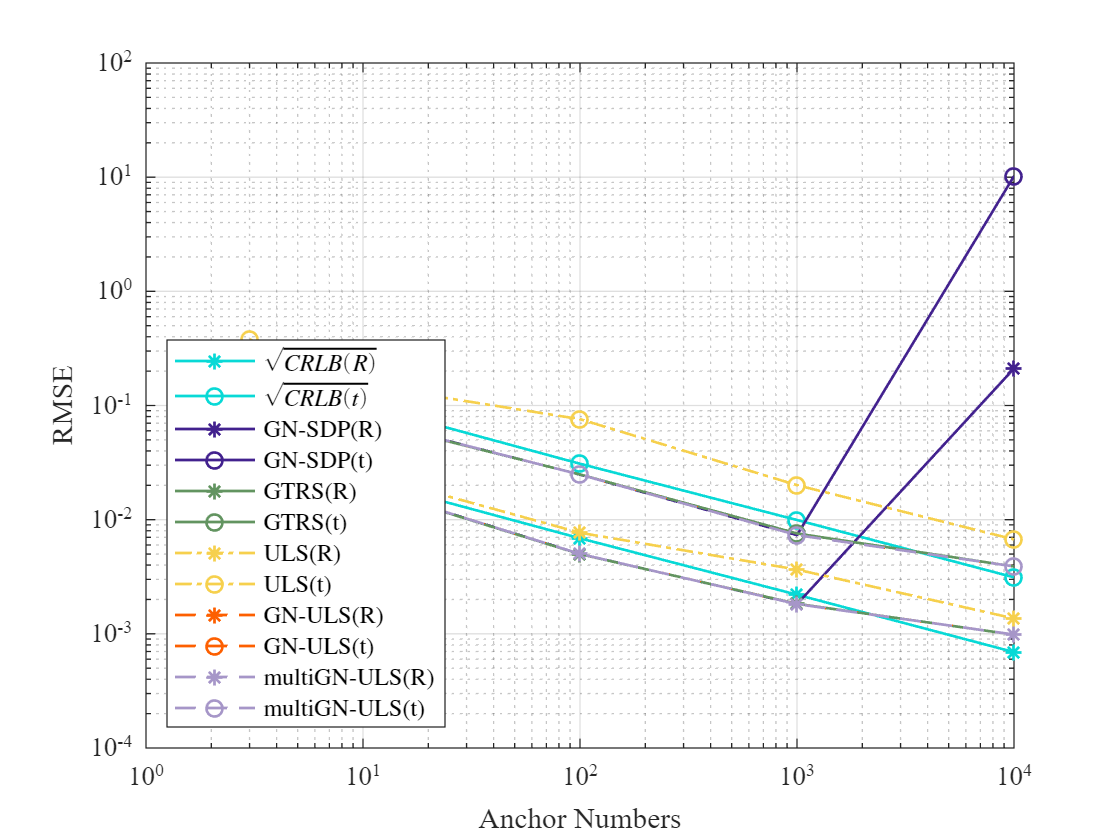

figure(1)
%CRLB
loglog(Q,CRLB(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
loglog(Q,CRLB(:,2),'-o','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
%one-step SDP
loglog(Q,Y1_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
loglog(Q,Y1_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
%GTRS
loglog(Q,Y2_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
loglog(Q,Y2_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
%UCLS
loglog(Q,Y0_r(:,1),'-.*','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
loglog(Q,Y0_r(:,3),'-.o','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%one-step UCLS
loglog(Q,Ye_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
loglog(Q,Ye_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
%multi-step UCLS
loglog(Q,Ym_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold on
loglog(Q,Ym_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold off

set(gca,'Fontname', 'Times New Roman')
xlabel('Anchor Numbers')
ylabel('RMSE')
legend({'$$\sqrt{CRLB(R)}$$','$$\sqrt{CRLB(t)}$$','GN-SDP(R)','GN-SDP(t)','GTRS(R)','GTRS(t)', ...
    'ULS(R)','ULS(t)','GN-ULS(R)','GN-ULS(t)','multiGN-ULS(R)','multiGN-ULS(t)'}, ...
    'interpreter','latex','Location','southwest')
grid on